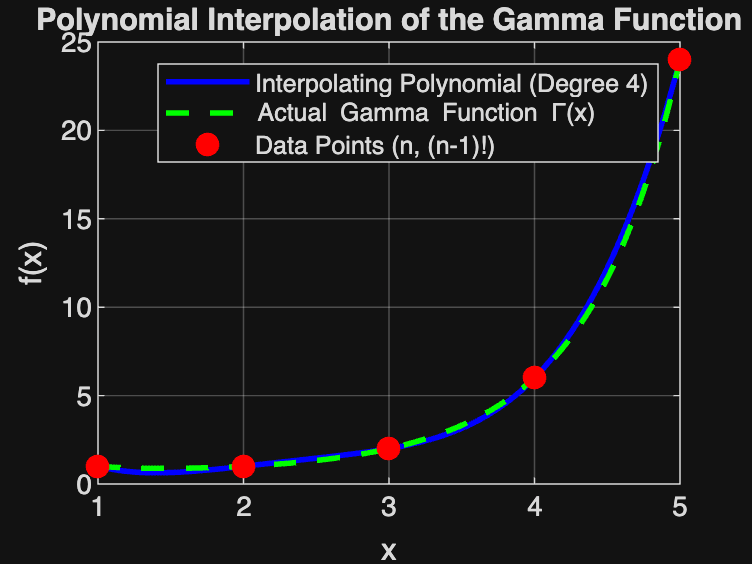

% Lab 2 3rd part
x_data = (1:5)';
f_data = [1; 1; 2; 6; 24];

u_plot = linspace(1, 5, 200)';

v_poly = newtondd(x_data, f_data, u_plot);

v_gamma = gamma(u);

%% --- Plotting ---
figure;
plot(u_plot, v_poly, 'b-', 'LineWidth', 2);
hold on;
plot(u_plot, v_gamma, 'g--', 'LineWidth', 2);
plot(x_data, f_data, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
title('Polynomial Interpolation of the Gamma Function');
xlabel('x');
ylabel('f(x)');
legend('Interpolating Polynomial (Degree 4)', 'Actual Gamma Function \Gamma(x)', 'Data Points (n, (n-1)!)');
grid on;
ylim([0 25]); % Adjust y-axis for better visualization

function v=newtondd(x,f,u)

%first create divided difference table
    n=length(x);
    F=zeros(n,n);

    F(:,1)=f;

    for j=2:n
        for i=j:n
            F(i,j)=(F(i,j-1)-F(i-1,j-1)) / (x(i)-x(i-j+1));
        end
    end

    coeff=diag(F)';

    v=zeros(size(u));
    for k=1:length(u)
        pval=coeff(n);

        for i=n-1:-1:1
            pval=pval*(u(k)-x(i))+coeff(i);
        end
        v(k)=pval;
    end  
end